`Student ID: 150144135`

`Module: Individual project`

`Year: 2018`

`Brief: This code creates a maze of (n x n) size from which the learning path is created and takes the form (n^2 x n^2). The SARSA and Q-learning algorithms are both used to demonstrate the agent's learning performance based on the parameters set. `

`Main`

clear all
close all

% Matrix used for question 3 in report to reveal preferred actions chosen - comment out every code before this line
load ('maze8x8.mat')
mazeSize = length(maze);

% Goal state in maze
maze(mazeSize,mazeSize) = 10;

% Set goal state for learning path
goal = mazeSize * mazeSize;

% Creating learning path for robot
path = [];

for i = 1:goal
    path = [path; reshape(maze', 1, goal)];
end

% There's no reward for any other action i.e. reward = 0
% and no unspecified action will occur
% 
% 4 directions/actions
% * Up     (i-mazeSize)
% * Down   (i+mazeSize)
% * Left   (i-1)
% * Right  (i+1)

for i = 1:goal
    for j = 1:goal      % 1                    2                     3                   4        ...    5 to 8 possible actions
        if not(j == i - mazeSize) && not(j == i + mazeSize) && not(j == i - 1) && not(j == i + 1) && not(j == i + mazeSize + 1) && not(j == i + mazeSize - 1) && not(j == i - mazeSize + 1) && not(j == i - mazeSize - 1)
            path(i,j) = 0;
        end
    end
end

% additional 4 diagonal directions = a total of 8 actions
% *  SE (i+mazeSize+1)
% *  SW (i+mazeSize-1)
% *  NE (i-mazeSize+1)
% *  NW (i-mazeSize-1)

% Set start and goal state in learning path
path(1,1) = 1;
path(goal,goal) = 10;

% Parameters
nTrial = 100;%50;
iteration = 50;%100;
discountFactor = 0.5;
learningRate = 0.9;
epsilon = 0.0010;

% Rewards matrices
sarsaLearning = zeros(iteration, nTrial);
qLearning = zeros(iteration, nTrial);

% Start

`SARSA Learning`

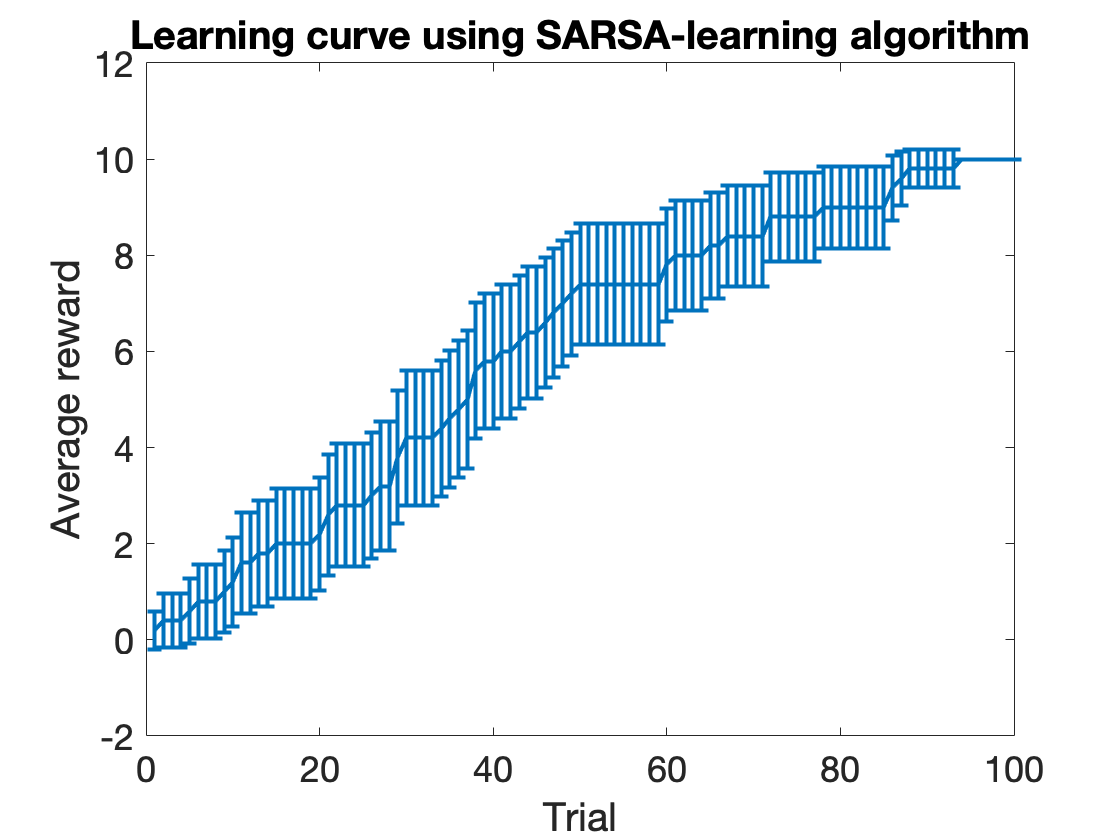

for i = 1:1:iteration
    tic
    [weight, sarsaLearning(i,:)] = Sarsa(path, goal, nTrial, learningRate, epsilon, discountFactor);
    t(i) = toc;
end

% average learning performance
sarsaAverageLearning = mean(sarsaLearning);

% with errorbars
sarsaError = 2 * std(sarsaLearning)./sqrt(iteration);

% Plot learning curve
sarsaAlgorithm = errorbar(sarsaAverageLearning, sarsaError);

% Plot properties
title('Learning curve using SARSA-learning algorithm')
set(sarsaAlgorithm, 'linewidth', 2);
xlabel('Trial', 'FontSize', 18);
ylabel('Average reward', 'FontSize', 18);
set(gca, 'fontsize', 18);

`Q-Learning`

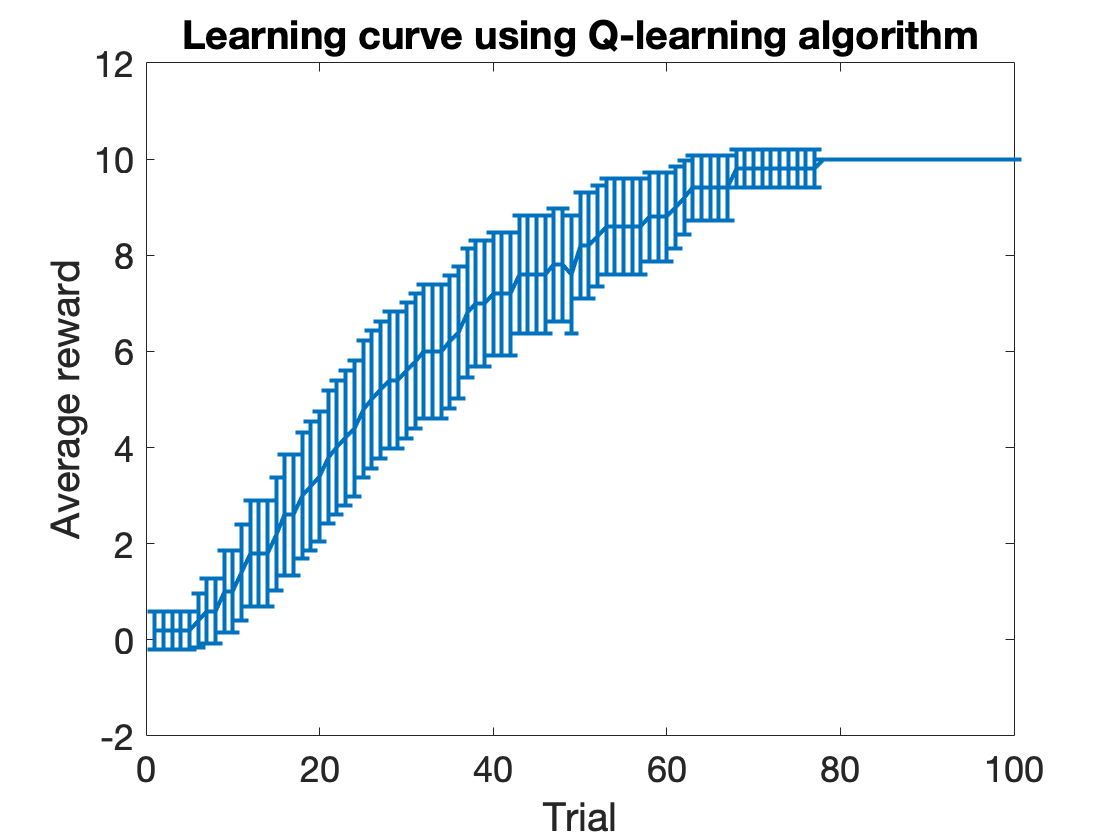

% for i = 1:1:iteration
%     tic
%     qLearning(i,:) = Qlearning(path, goal, nTrial, learningRate, epsilon, discountFactor);
%     t2(i) = toc;
% end
% 
% % average learning performance
% qAverageLearning = mean(qLearning);
% 
% % with errorbars
% qError = 2 * std(qLearning)./sqrt(iteration);
% 
% % Plot learning curve
% % hold on
% qAlgorithm = errorbar(qAverageLearning, qError); 
% 
% % Plot properties
% title('Learning curve using Q-learning algorithm')
% set(qAlgorithm, 'linewidth', 2);
% xlabel('Trial', 'FontSize', 18);
% ylabel('Average reward', 'FontSize', 18);
% set(gca, 'fontsize', 18);

% % Functions

`SARSA algorithm function`

function [weight, reward] = Sarsa(path, goal, nTrial, learningRate, epsilon, discountFactor)
    
%     number of states and actions
    nStates = size(path,1);
    nActions = size(path,2);
    
%     define & initialise matrices
    states = eye(nStates);
    reward = zeros(1,nTrial);
    weight = rand(nStates, nActions);
    
%     begin episode
    for trial = 1:nTrial
        
%         eligibityTrace = weight;
        
%         place robot at random state
        currentState = randi([1 length(path)], 1, 1);
        
%         define & initialise the variables needed in sarsa algorithm for each trial
        oldInput = zeros(nStates,1);
        oldOutput = zeros(nActions,1);
        oldQvalue = 0;
        oldReward = 0;       
        
%         repeat till goal state is reached
        while(1)
            
%             convert initial state into vector
            input = states(:,currentState);
            
%             find states/room to go to based on current state
            actions = find(path(currentState,:) > 0);
            
%             computes the q-value and sort in descending order
            Qvalue = 1 ./ (1 + exp(-weight * input));
           
            %         ε-Greedy algorithm
            epsilonNotGreedy = rand < epsilon;
            
%             if not greedy and it can't go to a room, find others
            while and(isempty(actions), epsilonNotGreedy)
                currentState = randi([1 length(path)], 1, 1);
                actions = find(path(currentState,:) > 0);
            end
            
%             not greedy
            if epsilonNotGreedy
%                 pick random q value from possible actions
                q = Qvalue(actions(randi(length(actions), 1)), 1);
                
            else % if greedy
%                 pick max q value available
                q = max(Qvalue);
            end
            
%             take next action based on q-value
            for i = 1:length(Qvalue)
                if Qvalue(i,1) == q
                    newState = i;
                end
            end
            
%             collect reward
            if newState == goal                   % did robot make correct action ?
                r = path(currentState, newState); % learn current position
            else
                r = 0;                          % else learn nothing
            end
            
        % % % % % % % % % % % % % % % % % % % % % % % % % %        
%             Updates

%             rectified output to update the weight only to the neuron whose action is selected
            output = zeros(nActions,1);
            output(newState, 1) = 1;
            
%             weight matrix
            weight = weight + learningRate * (oldReward - oldQvalue + discountFactor * q) * oldOutput * oldInput';

%             variables for sarsa algorithm
            oldQvalue = q;
            oldOutput = output;
            oldInput = input;
            oldReward = r;
        % % % % % % % % % % % % % % % % % % % % % % % % % %  

%             reached goal state ?
            if currentState == goal
                break;                  % terminate
            else
                currentState = newState;  % else selected action becomes new current state
            end  
            
        end % while loop
        
%         update weight for terminal state with no next action (reset)
        weight = weight + learningRate * (oldReward - oldQvalue) * oldOutput * oldInput';
        
%         store reward for the current trial
        reward(1,trial) = oldReward;
        
    end % for loop
end % function

`Q learning function`

function reward = Qlearning(path, goal, nTrial, learningRate, epsilon, discountFactor)
    
    Qvalue = rand(size(path));
    
    reward = zeros(1,nTrial);
    
    for trial = 1:nTrial

%         place robot at random state
        currentState = randi([1 length(path)], 1, 1);
        
%         define & initialise the variables needed in q learning algorithm for each trial
        oldReward = 0;
        oldQvalue = 0;
        
        while(1)

%             find states/room to go to based on current state
            actions = find(path(currentState,:) > 0);
            
%             computes the q-value and sort in descending order
            maxQvalue = max(Qvalue,[],2);
            
%             ε-Greedy algorithm
            epsilonNotGreedy = (rand < epsilon);
            
%             if not greedy and it can't go to a room, find others
            while and(isempty(actions), epsilonNotGreedy)
                currentState = randi([1 length(path)], 1, 1);
                actions = find(path(currentState,:) > 0);
            end
            
%             not greedy
            if epsilonNotGreedy
%                 pick random q value from possible actions
                q = Qvalue(currentState, actions(randi(length(actions),1)));
                
            else % if greedy
%                 pick max q value available
                q = max(Qvalue(currentState, :));
            end
            
%             take action based on q-value
            for i = 1:size(Qvalue,2)
                if Qvalue(currentState,i) == q
                    newState = i;
                end
            end
            
%             collect reward
            if newState == goal                   % did robot make correct action ?
                r = path(currentState,newState); % learn current position
                
            else
                r = 0;                          % else learn nothing
            end
            
%             updates q value
            Qvalue(currentState, newState) = Qvalue(currentState, newState) + learningRate * (oldReward - oldQvalue + discountFactor * maxQvalue(newState,1));
            
%             and variables for q learning algorithm
            oldReward = r;
            oldQvalue = maxQvalue(newState,1);
            
%             reached goal state ?
            if currentState == goal
                break;                  % terminate
            else
                currentState = newState;  % else selected action becomes new current state
            end
            
        end % while loop
        
%         update Q values
        Qvalue(currentState, newState) = Qvalue(currentState, newState) + learningRate * (oldReward - oldQvalue);
        
%         store reward for the current trial
        reward(1,trial) = oldReward;
    end % for loop
end